clear all;
% innitialization
HDRNames = [5,19,34,39,42,43,78,80,102,105,125,152,164,183,198,201,202,203,209,222,226,227,230,232,243,259,272,278,281,282];
HDRNum = [1,2,3,4,5,6,7,8,9,10,11,12,13,14,15,16,17,18,19,20,21,22,23,24,25,26,27,28,29,30];

% data1
load("./GRIs/used_illumination_v2.mat");
illum_exp = illumination_variable;

name1 = illum_exp.name;
name1_numeric = str2double(name1);
[tf, loc] = ismember(name1_numeric, HDRNames); 
name2 = HDRNum(loc);                   
name2 = string(name2);
disp(name2);

  1 列から 14 列

    "9"    "10"    "11"    "12"    "13"    "14"    "2"    "15"    "16"    "17"    "18"    "19"    "20"    "21"

  15 列から 28 列

    "22"    "23"    "24"    "25"    "26"    "27"    "28"    "29"    "30"    "3"    "4"    "5"    "6"    "1"

  29 列から 30 列

    "7"    "8"



illum_exp.name2 = transpose(name2);

illum_exp_name = illum_exp.name2;
illum_exp_gri = illum_exp.result_IRI;

graphTable = illum_exp(:,{'name2','result_IRI'});
graphTable.Properties.VariableNames = {'name', 'GRI'};

graphTable.Group = repmat("A", height(graphTable), 1);

% data1.5
load("./GRIs/lummodel_data.mat");
LumModelH = lummodelH;
Error_LumModelH = zeros(size(LumModelH));
LumModelNormH = lummodelNormH;
LumModelZsH = lummodelZsH;

illum_exp_v2_name = transpose(string(HDRNum));
illum_exp_v2_gri = LumModelH;

graphv2Table = table(illum_exp_v2_name,illum_exp_v2_gri);
graphv2Table.Properties.VariableNames = {'name', 'GRI'};

graphv2Table.Group = repmat("A", height(graphv2Table), 1);

% data2
load("./GRIs/maked_illumination.mat");
illum_test = illumination_variable;

illum_test_name = illum_test.name;
illum_test_gri = illum_test.result_IRI;

addTable = illum_test(:,{'name','result_IRI'});
addTable.Properties.VariableNames = {'name', 'GRI'};

addTable.Group = repmat("B", height(addTable), 1);

% 結合
%jointTable = [graphTable;addTable];
jointTable = [graphv2Table;addTable];
jointTable = sortrows(jointTable, 'GRI');

idxA = jointTable.Group == "A";
idxB = jointTable.Group == "B";

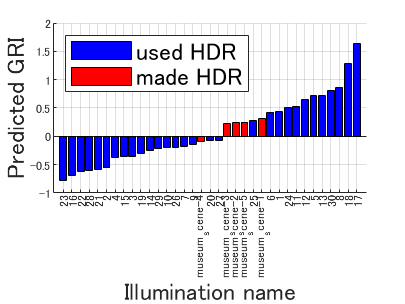

% makegraph
% initial
amp = 1;
x_label = "Illumination name";
y_label = "Predicted GRI";
x_ticklabels = jointTable.name;
x = 1:height(jointTable);

%plot
figure;
hold on;
barA = bar(x(idxA), jointTable.GRI(idxA), 'FaceColor', 'b');
barB = bar(x(idxB), jointTable.GRI(idxB), 'FaceColor', 'r');
hold off;

% axis
set(gca, 'XTick', x);
xticklabels(x_ticklabels);
xtickangle(90);
set(gca,'FontSize',6*amp);

% label
xlabel(x_label,'FontSize',12*amp); 
ylabel(y_label,'FontSize',12*amp);
legend([barA, barB],{'used HDR', 'made HDR'},'Location', 'northwest','Orientation','vertical','FontSize',12*amp);
grid on;
plotname = strcat('./images/illumination_GRI_v2.jpg');
saveas(gcf, plotname);